%% Abalone Age Prediction Example
% This script demonstrates training a deep neural network to predict the age
% of abalone from physical measurements.
%
% DATA SOURCE:
% The Abalone dataset is publicly available from the UCI Machine Learning Repository:
%   https://archive.ics.uci.edu/ml/datasets/abalone
%
% DATA PREPARATION:
% 1. Download "abalone.data" from the link above.
% 2. Convert it into MATLAB format (.mat) as follows:
%    - Load into MATLAB using `readtable`:
%         T = readtable('abalone.data', 'FileType', 'text', 'ReadVariableNames', false);
%    - The dataset contains one categorical feature ('Sex') followed by numeric features.
%      You should convert 'Sex' to numeric codes or one-hot encoding, then append the rest.
%    - Store the numeric matrix in a variable named `data`, where:
%        Columns 1:end-1 → features
%        Last column      → age (computed as Rings + 1.5)
%    - Save as:
%         save('abalone_dataset.mat', 'data');
%
% This script assumes you already have 'abalone_dataset.mat' in the working directory.

clear; clc;

%% Load dataset
load('abalone_dataset.mat');  % Contains variable 'data'

% Target variable: age (last column)
age = data(:, end);

% Replace NaNs with zeros
data(isnan(data)) = 0;

% Feature matrix (transpose so that columns are samples)
X = data(:, 1:end-1)';

% Normalize features: zero mean, unit variance, scaled by 1/sqrt(8)
X = (1/sqrt(8)) * ((X - mean(X, 2)) ./ std(X, 0, 2));

%% Split data into training and test sets (80% / 20%)
numSamples = size(X, 2);
rng(1);  % For reproducibility
cv = cvpartition(numSamples, 'HoldOut', 0.2);

XTrainFull = X(:, training(cv));
YTrainFull = age(training(cv));
XTest  = X(:, test(cv));
YTest  = age(test(cv));

%% Further split training set into train/validation (80% / 20%)
numTrainSamples = size(XTrainFull, 2);
cvVal = cvpartition(numTrainSamples, 'HoldOut', 0.2);

XTrain = XTrainFull(:, training(cvVal));
YTrain = YTrainFull(training(cvVal));
XVal   = XTrainFull(:, test(cvVal));
YVal   = YTrainFull(test(cvVal));

%% Normalize targets using training set statistics
YTrainMean = mean(YTrain);
YTrainStd  = std(YTrain);

YTrainNorm = (YTrain - YTrainMean) / YTrainStd;
YValNorm   = (YVal   - YTrainMean) / YTrainStd;


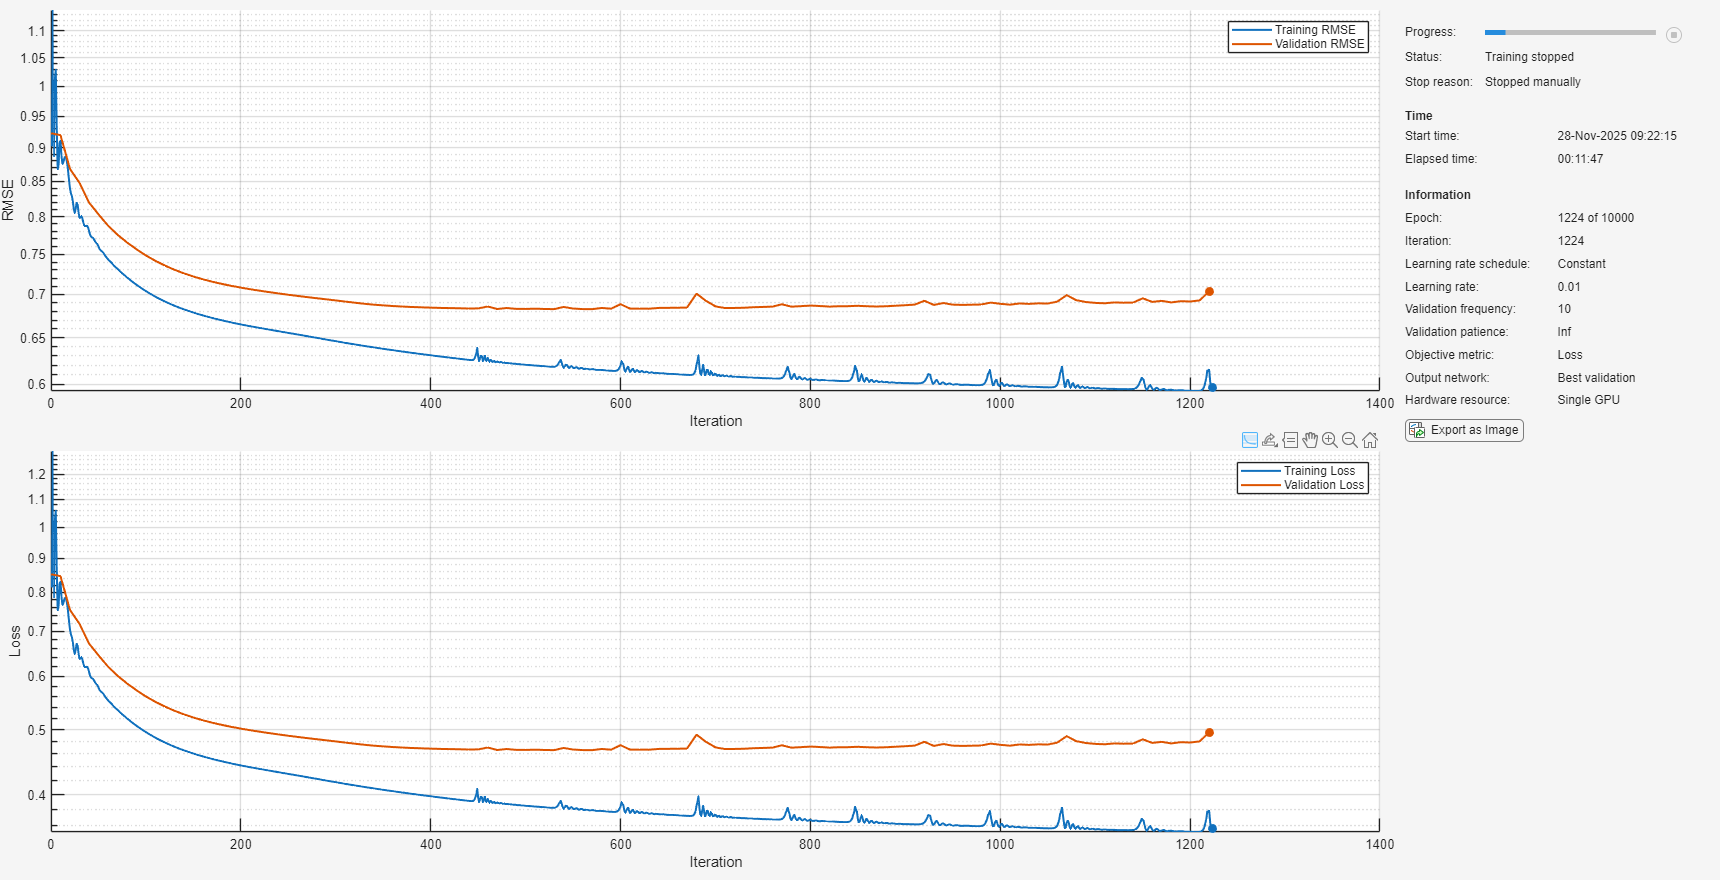

%% Define network layers
% NOTE: You must define `customWeights1`, `customWeights2`, and `customWeights3`
%       as separate functions that return weight initializations.
layers = [
    featureInputLayer(size(XTrain, 1))
    fullyConnectedLayer(16000, 'WeightLearnRateFactor', 0, ...
        'WeightsInitializer', @customWeights1_git, ...
        'BiasL2Factor', 0, 'BiasInitializer', 'zeros')
    tanhLayer
    fullyConnectedLayer(16000, 'WeightLearnRateFactor', 0, ...
        'WeightsInitializer', @customWeights2_git, ...
        'BiasL2Factor', 0, 'BiasInitializer', 'zeros')
    tanhLayer
    fullyConnectedLayer(1, 'Name', 'output', ...
        'WeightLearnRateFactor', 0, ...
        'WeightsInitializer', @customWeights3_git, ...
        'BiasL2Factor', 0, 'BiasInitializer', 'zeros')
];

%% Create deep learning network
net = dlnetwork(layers);

%% Convert training and validation data to dlarray
XTrain_dl = dlarray(single(XTrain), "CB");  % C = Channel, B = Batch
XVal_dl   = dlarray(single(XVal), "CB");

%% Training options
options = trainingOptions('adam', ...
    'MaxEpochs', 10000, ...
    'Metrics', "rmse", ...
    'MiniBatchSize', 4177, ...
    'InitialLearnRate', 0.01, ...
    'Shuffle', 'every-epoch', ...
    'ValidationData', {XVal_dl, YValNorm}, ...
    'Plots', "training-progress", ...
    'Verbose', 0, ...
    'ValidationFrequency', 10);

%% Train network
[net, tr] = trainnet(XTrain_dl, YTrainNorm, net, 'mse', options);

%% Predict on test set
XTest_dl = dlarray(single(XTest), "CB");
YpredNorm = predict(net, XTest_dl);

% Convert predictions back to original scale
Ypred = YpredNorm * YTrainStd + YTrainMean;


%% Evaluate performance (signed error distribution + Pearson r)
% Ensure predictions/targets are plain numeric arrays (not dlarray/gpu types)
YpredNum = Ypred;
if isa(YpredNum,"dlarray"),  YpredNum = extractdata(YpredNum); end
if isa(YpredNum,"gpuArray"), YpredNum = gather(YpredNum); end
YpredNum = double(YpredNum(:));

YTestNum = YTest;
if isa(YTestNum,"dlarray"),  YTestNum = extractdata(YTestNum); end
if isa(YTestNum,"gpuArray"), YTestNum = gather(YTestNum); end
YTestNum = double(YTestNum(:));

% Common finite mask (apply consistently)
m = isfinite(YpredNum) & isfinite(YTestNum);
YpredNum = YpredNum(m);
YTestNum = YTestNum(m);

% Signed error: prediction - truth (positive = over-predict)
signedError = YpredNum - YTestNum;

% Error stats
muSigned       = mean(signedError);
sdSigned       = std(signedError, 0);
medianAbsError = median(abs(signedError));

% Pearson correlation (pred vs true)
if numel(YTestNum) >= 2 && std(YTestNum) > 0 && std(YpredNum) > 0
    [rPearson, pPearson] = corr(YpredNum, YTestNum, 'Type','Pearson', 'Rows','complete');
else
    rPearson = NaN; pPearson = NaN;
end

fprintf('Median Absolute Error on Test Set: %.4f years\n', medianAbsError);

Median Absolute Error on Test Set: 1.0573 years


fprintf('Signed Error Mean (bias):          %.4f years\n', muSigned);

Signed Error Mean (bias):          -0.0478 years


fprintf('Signed Error Std Dev:              %.4f years\n', sdSigned);

Signed Error Std Dev:              2.0801 years


fprintf('Pearson r(pred,true):              %.4f (p=%.3g)\n', rPearson, pPearson);

Pearson r(pred,true):              0.7653 (p=1.56e-161)


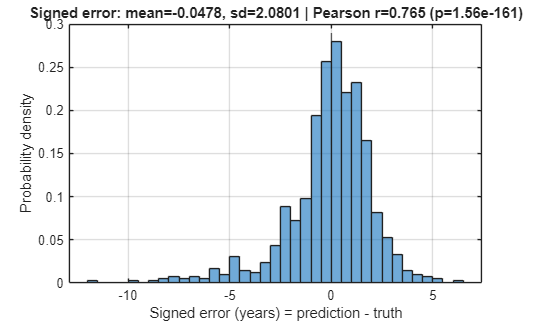


% Plot distribution (explicit binning for robustness)
figure;  % (no figure name set)
histogram(signedError, 'Normalization','pdf', 'BinMethod','fd');
grid on; xline(0,'--');
xlabel('Signed error (years) = prediction - truth');
ylabel('Probability density');
title(sprintf('Signed error: mean=%.4f, sd=%.4f | Pearson r=%.3f (p=%.3g)', ...
    muSigned, sdSigned, rPearson, pPearson));